close("all"); clear; clc;
setmadsympath();

## Rigid bodies

t = sym('t');
N = Frame;
O = Point;

### Rear contact point

Orientation:

yaw = DynamicVariable("psi");
Nyaw = N.orientNew('z',yaw.state);
pprint(Nyaw.dcm);

$$\left[\begin{array}{ccc} c_{\psi } & -s_{\psi } & 0\\ s_{\psi } & c_{\psi } & 0\\ 0 & 0 & 1 \end{array}\right]$$

Position:

prx = DynamicVariable("p_x");
pry = DynamicVariable("p_y");
rOCr = prx.state.*N.x + pry.state.*N.y;
Cr = O.locateNew(rOCr);

### Rear wheel

Orientation:

lean = DynamicVariable("varphi");
Nlean = Nyaw.orientNew('x',lean.state);
pitch_r = DynamicVariable("theta_r");
Npitch_r = Nlean.orientNew('y',pitch_r.state);
pprint(Npitch_r.dcm);

$$\left[\begin{array}{ccc} c_{\psi }\,c_{\theta ,r}-s_{\psi }\,s_{\theta ,r}\,s_{\phi } & -c_{\phi }\,s_{\psi } & c_{\psi }\,s_{\theta ,r}+c_{\theta ,r}\,s_{\psi }\,s_{\phi }\\ c_{\theta ,r}\,s_{\psi }+c_{\psi }\,s_{\theta ,r}\,s_{\phi } & c_{\psi }\,c_{\phi } & s_{\psi }\,s_{\theta ,r}-c_{\psi }\,c_{\theta ,r}\,s_{\phi }\\ -c_{\phi }\,s_{\theta ,r} & s_{\phi } & c_{\theta ,r}\,c_{\phi } \end{array}\right]$$

Position:

rr = newParameters("r_r");
Or = Cr.locateNew(-rr.*Nlean.z);

Rigid body : 

iry = newParameters('i_ry');
Irw = inertia(0,iry,0);
Br = Body(Npitch_r,Or,Irw,0);

### Rear chassis

Orientation:

pitch = DynamicVariable("theta");
Npitch = Nlean.orientNew('y',pitch.state);
pprint(Npitch.dcm);

$$\left[\begin{array}{ccc} c_{\psi }\,c_{\theta }-s_{\psi }\,s_{\theta }\,s_{\phi } & -c_{\phi }\,s_{\psi } & c_{\psi }\,s_{\theta }+c_{\theta }\,s_{\psi }\,s_{\phi }\\ c_{\theta }\,s_{\psi }+c_{\psi }\,s_{\theta }\,s_{\phi } & c_{\psi }\,c_{\phi } & s_{\psi }\,s_{\theta }-c_{\psi }\,c_{\theta }\,s_{\phi }\\ -c_{\phi }\,s_{\theta } & s_{\phi } & c_{\theta }\,c_{\phi } \end{array}\right]$$

Position:

[b,h] = newParameters('b','h');
Ob = Cr.locateNew(b.*Npitch.x - h.*Npitch.z);

Rigid body :

mb = newParameters('m_b');

names = {
    'I_bx';
    'I_by';
    'I_bz'
    };

[Ibx,Iby,Ibz] = newParameters(names{:});
Cbxz = newParameters("C_bxz");
Ib = inertia(Ibx,Iby,Ibz,'Ixz',Cbxz);
Bb = Body(Npitch,Ob,Ib,mb);

### Front contact point

Orientation :

yaw_f = DynamicVariable("psi_f");
Nyaw_f = N.orientNew('z',yaw_f.state);

Position : 

pfx = DynamicVariable("p_fx");
pfy = DynamicVariable("p_fy");
rOCf = pfx.state.*N.x + pfy.state.*N.y;
Cf = O.locateNew(rOCf);

### Front wheel

Orientation :

lean_f = DynamicVariable("varphi_f");
Nlean_f = Nyaw_f.orientNew('x',lean_f.state);
pitch_f = DynamicVariable("theta_f");
Npitch_f = Nlean_f.orientNew('y',pitch_f.state);

Position :

rf = sym("r_f");
Of = Cf.locateNew(-rf.*Nlean_f.z);

Rigid body : 

ify = newParameters('i_fy');
Ifw = inertia(0,ify,0);
Bf = Body(Npitch_f,Of,Ifw,0);

### Front chassis

Orientation:

reach = DynamicVariable("beta");
Nreach = Nlean_f.orientNew('y',reach.state);

Position:

[lfx,lfz] = newParameters("l_fx","l_fz");
rOfOh = lfx.*Nreach.x + lfz.*Nreach.z;
Oh = Of.locateNew(rOfOh);

Rigid body :

names = {
    'm_h';
    'I_hx';
    'I_hz'
    };

[mh,Ihx,Ihz] = newParameters(names{:});
Ih = inertia(Ihx,0,Ihz);
Bh = Body(Nreach,Oh,Ih,mh);

## Forces and moments

### Rear tire

Slip angle :

VCr = Twist(Pose(Nyaw,Cr)).vector();
slip_r = atan(VCr(5)/VCr(4));

Lateral force :

[Cr1,Cr2] = newParameters("C_r1","C_r2");
Yr = Cr1.*slip_r + Cr2.*lean.state;

Normal force :

Zr = sym("Z_r");
Br.applyForce(Nyaw,Cr,[0,Yr,-Zr].');

### Front tire

Slip angle :

VCf = Twist(Pose(Nyaw_f,Cf)).vector();
slip_f = atan(VCf(5)/VCf(4));

Lateral force :

[Cf1,Cf2] = newParameters("C_f1","C_f2");
Yf = Cf1.*slip_f + Cf2.*lean_f.state;

Normal force :

Zf = sym("Z_f");
Bf.applyForce(Nyaw_f,Cf,[0,Yf,-Zf].');

### Steering torque

Orientation :

caster = sym("varepsilon");
Ncaster = Npitch.orientNew('y',caster);
steer = DynamicVariable("delta");
Nsteer = Ncaster.orientNew('z',steer.state);

Moment :

Msteer = DynamicVariable("tau_delta");
Csteer = newParameters('C_delta');
Mz = Msteer.state - Csteer*steer.rate;
Bh.applyMoment(Nreach,Mz.*N.z);
Bb.applyMoment(Nsteer,-Mz.*N.z);

### Throttle torque

Mthrot = DynamicVariable("tau_theta_r");
Br.applyMoment(Npitch_r,Mthrot.state.*N.y);
Bb.applyMoment(Npitch_r,-Mthrot.state.*N.y);

### Gravity

B = [
    Bb;
    Br;
    Bh;
    Bf
    ];

g = newParameters('g');
fp = @(b)b.MassCenter;
fFg = @(b)(b.Mass*g).*N.z;
fg = @(b)b.applyForce(N,fp(b),fFg(b));
arrayfun(fg,B);

## Generalized coordinates

q = [
    yaw;
    lean;
    pitch;
    prx;
    pry;
    yaw_f;
    lean_f;
    reach;
    pfx;
    pfy;
    pitch_r;
    pitch_f;
    steer
    ];

## Kinematics

Rear chassis angular velocities :

wbx = DynamicVariable("omega_bx");
wby = DynamicVariable("omega_by");
wbz = DynamicVariable("omega_bz");
wb = [wbx,wby,wbz].';

Vb = Twist(Pose(Npitch,Ob)).vector();

kdes_b = wb.state - Vb(1:3);

Rear contact velocity :

VCr = Twist(Pose(Nyaw,Cr)).vector();

vCrx = DynamicVariable("v_Crx");
vCry = DynamicVariable("v_Cry");

kdes_Cr = [
    vCrx.state - VCr(4);
    vCry.state - VCr(5);
    ];

Front chassis angular velocities :

whx = DynamicVariable("omega_hx");
why = DynamicVariable("omega_hy");
whz = DynamicVariable("omega_hz");
wh = [whx,why,whz].';

Vh = Twist(Pose(Nreach,Oh)).vector();

kdes_h = wh.state - Vh(1:3);

Front contact velocity :

VCf = Twist(Pose(Nyaw_f,Cf)).vector();

vCfx = DynamicVariable("v_Cfx");
vCfy = DynamicVariable("v_Cfy");

kdes_Cf = [
    vCfx.state - VCf(4);
    vCfy.state - VCf(5);
    ];

Wheel velocities :

wr = DynamicVariable("omega_r");
wf = DynamicVariable("omega_f");

kdes_wheels = [
    wr.state - pitch_r.rate;
    wf.state - pitch_f.rate
    ];

Steer velocity :

wsteer = DynamicVariable("omega_delta");
kdes_steer = wsteer.state - steer.rate;

### Generalized speeds

u = [
    wbx;
    wby;
    wbz;
    wr;
    vCrx;
    vCry;
    whx;
    why;
    whz;
    wf;
    vCfx;
    vCfy;
    wsteer
    ];

### Kinematic differential equations

kdes = [
    kdes_b;
    kdes_Cr;
    kdes_h;
    kdes_Cf;
    kdes_wheels;
    kdes_steer
    ];

## Equations of motion

F = [
    Msteer;
    Mthrot
    ];

eom = kanesMethod(q,u,kdes,B,F);

## Configuration constraints

Connect rear and front frames :

hcNrf = Nreach.y - Nsteer.y;

Steering axis - caster chord intercept :

a = sym('a');
Pa = Ob.locateNew(h.*Npitch.z);
Pb = Pa.locateNew(a.*Ncaster.x);

Front wheel center :

[lx,lz] = newParameters("l_x","l_z");
rBOf = lx.*Nsteer.x + lz.*Nsteer.z;
Pf = Pb.locateNew(rBOf);

Orientation :

ang = reach.state - caster;
Nc = Nsteer.orientNew('y',ang);

Position :

PCf = Pf.locateNew(rf.*Nc.z);
rOCf = PCf.posFrom();

Reach constraint

hc_reach = N.z.'*diff(rOCf,reach.state);

### Holonomic constraints

hc = [
    hcNrf;
    rOCf;
    hc_reach
    ];

hc = simplify(expand(hc));

## Velocity constraints

Rear no-slip :

rOrCr = Cr.posFrom(Or,Npitch_r);
nhcr = noslip(Br,rOrCr,Nyaw);

Front no-slip :

rOfCf = Cf.posFrom(Of,Npitch_f);
nhcf = noslip(Bf,rOfCf,Nyaw_f);

### Nonholonomic constraints

nhc = [
    nhcr(1);
    nhcf(1)
    ];

## Constraint jacobian

cons = [
    diff(hc,t);
    nhc
    ];

Aqd = jacobian(cons,q.rate);
eomk = eom.Kinematics;
A = simplify(expand(Aqd*eomk.Jacobian));
Ad = subs(diff(A,t),q.rate,eomk.ForcingVector);

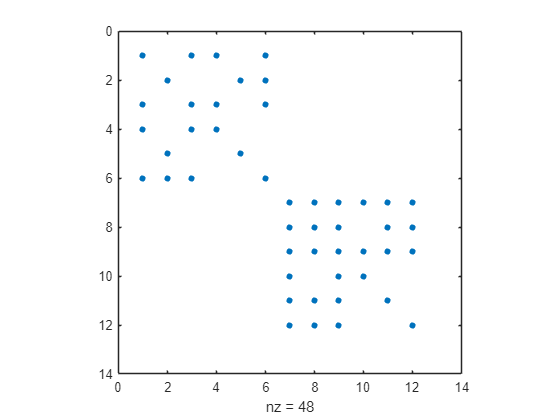

eomd = simplify(sum(eom.BodyDynamics));
Md = simplify(eomd.MassMatrix);
spy(Md)

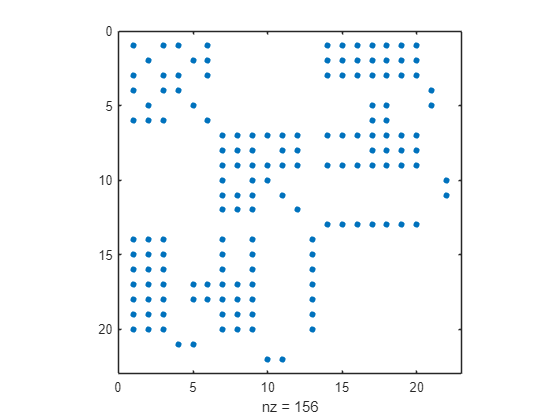

nc = size(A,1);

Mc = [
    Md,A.';
    A,zeros(size(A,1),size(A,1))
    ];

fc = [
    simplify(expand(eomd.ForcingVector));
    -Ad*u.state
    ];

spy(Mc)